clc
close all
clearvars

group = "wt";
exp_num = "exp1";
calib_dir = fullfile(pwd,strcat("fusion_",exp_num),strcat("benchmark_",group));
data_dir = fullfile(pwd,"mgat1ko_data",strcat(group,"-preprocessed-25s"));

current_names = {'iktof','ikslow1','ikslow2','ikss'};

tune_idx = cell(5,1);
tune_idx{1} = [1,2,3,4,5,7,11,13];
tune_idx{2} = [2,3];
tune_idx{3} = [1,2,4,5,9,10,11];
tune_idx{4} = [1,2,3];
tune_idx{5} = [1,2,3,4];

pdefault = cell(5,1);
pdefault{1} = [33,15.5,20,7,0.03577,0.06237,0.18064,0.3956,...
    0.000152,0.067083,0.00095,0.051335,0.3846];
pdefault{2} = [-1050,270,0.0629];
pdefault{3} = [22.5,45.2,40.0,7.7,5.7,0.0629,6.1,18,2.058,803.0,0.16];
pdefault{4} = [4912,5334,0.16];
pdefault{5} = [0.0862,1235.5,13.17,0.0611];

[mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx);

matching_table = readtable(fullfile(pwd,"mgat1ko_data",strcat("matching-table-",group,".xlsx")));
file_names = matching_table.trace_file_name_25;
file_names(cellfun(@isempty,file_names)) = [];
file_names = string(file_names);
num_files = length(file_names);

holdv = -70;
testv = 50;
ek = -91.1;

ideal_holdt = 470;
ideal_endt = 25*1000;

protocol = cell(6,1);
protocol{1} = holdv;
protocol{2} = ek;
protocol{3} = testv;

file_names(cellfun(@isempty,file_names)) = [];
file_names = string(file_names);
num_files = length(file_names);

sol = table2array(readtable(fullfile(calib_dir,file_names(1))));
sol = gen_sol_vec(sol,mdl_struct,psize);

exp_data = table2array(readtable(fullfile(data_dir,file_names(1))));
t = exp_data(:,1);
yksum = exp_data(:,2:end);

[~, ideal_hold_idx] = min(abs(t-ideal_holdt));
[~, ideal_end_idx] = min(abs(t-ideal_endt));
t = t(1:ideal_end_idx);
yksum = yksum(1:ideal_end_idx,:);

protocol{4} = t;
protocol{5} = t(1:ideal_hold_idx);
pulse_t = t(ideal_hold_idx+1:end);
pulse_t_adj = pulse_t - pulse_t(1);
protocol{6} = pulse_t_adj;

ymx = kcurrent_basic(sol, mdl_struct, pdefault, protocol, testv);
yhat = sum(ymx,2);

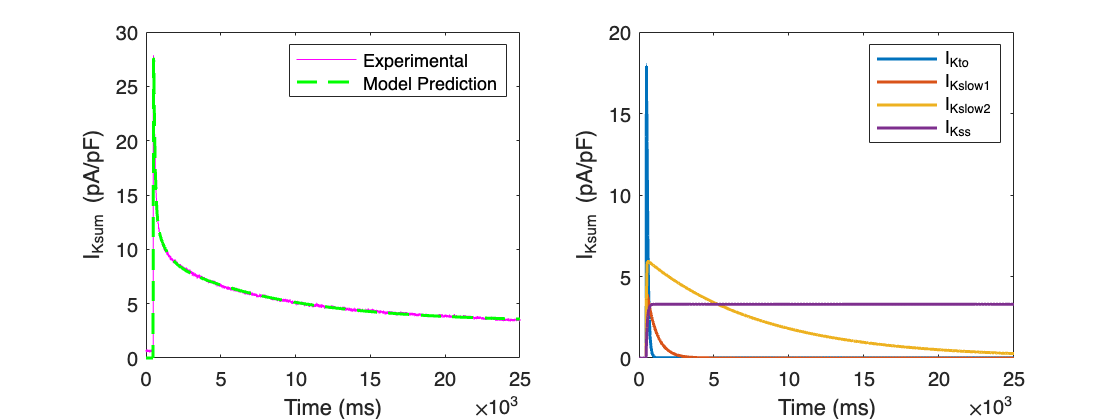

figure('Position',[10,10,560,210])

subplot(1,2,1)
plot(t,yksum,'-','Color','magenta')
hold on
plot(t,yhat,'--','Color','green','LineWidth',1.5)
hold off
ax=gca; 
ax.XAxis.Exponent = 3;
xlabel("Time (ms)")
ylabel("I_{Ksum} (pA/pF)")
legend(["Experimental","Model Prediction"])

subplot(1,2,2)
plot(t,ymx,'LineWidth',1.5)
ax=gca; 
ax.XAxis.Exponent = 3;
xlabel("Time (ms)")
ylabel("I_{Ksum} (pA/pF)")
legend(["I_{Kto}","I_{Kslow1}","I_{Kslow2}","I_{Kss}"])

# Custom functions

function [mdl_struct, psize] = gen_mdl_struct(current_names, tune_idx)
    num_currents = length(current_names);
    
    % index 1
    idx_info1 = cell(1,num_currents);
    for i = 1:num_currents
        switch current_names{i}
            case 'iktof'
                idx_info1{i} = tune_idx{1};
            case 'iktos'
                idx_info1{i} = tune_idx{2};
            case 'ikslow1'
                idx_info1{i} = tune_idx{3};
            case 'ikslow2'
                idx_info1{i} = tune_idx{4};
            case 'ikss'
                idx_info1{i} = tune_idx{5};
        end
    end

    % index 2
    idx_info2 = cell(1,num_currents);
    psize = 0;
    for i = 1: num_currents
        psize_old = psize;
        psize = psize + length(idx_info1{i});
        idx_info2{i} = (1+psize_old):(psize);
    end

    model_info = [current_names; idx_info1; idx_info2];
    field_names = ["name","idx1","idx2"];
    mdl_struct = cell2struct(model_info, field_names, 1);    
end

function sol = gen_sol_vec(sol_mx, model_struct, psize)
    sol = zeros(1, psize);
    for i = 1:length(model_struct)
        running_sol = sol_mx(:, i);
        running_sol = running_sol(~isnan(running_sol));
        sol(model_struct(i).idx2) = running_sol(model_struct(i).idx1);
    end
end